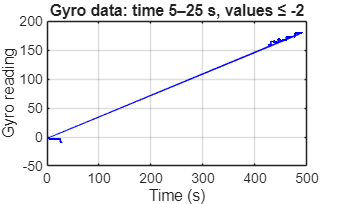

fname = 'pendulum_calibration_data.txt';

data = readmatrix(fname);

t = data(:,1);
y = data(:,2);

figure
plot(t, y, '-b', 'LineWidth', 1)
xlabel('Time (s)')
ylabel('Gyro reading')
title('Gyro data: time 5–25 s, values ≤ -2')
grid on


mask = (t >= 5) & (t <= 25) & (y <= -2);

t_sel = t(mask); t_sel = t_sel   - t_sel(1)

t_sel =          0
    0.0100
    0.0200
    0.0300
    0.0400
    0.0500
    0.0600
    0.0700
    0.0800
    0.0900
    0.1000
    0.1100
    0.1200
    0.1300
    0.1400


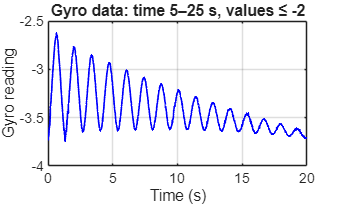

y_sel = y(mask);

figure
plot(t_sel, y_sel, '-b', 'LineWidth', 1)
xlabel('Time (s)')
ylabel('Gyro reading')
title('Gyro data: time 5–25 s, values ≤ -2')
grid on

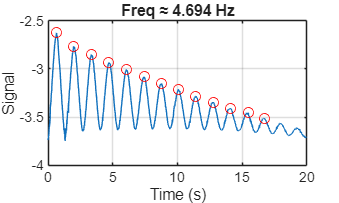

[~,locs] = findpeaks(y_sel, t_sel, 'MinPeakProminence', 0.12);
periods = diff(locs);
periods = periods(isfinite(periods) & periods>0);
fn_time = (2*pi)/mean(periods);

length = 9.8/(fn_time^2);

figure
plot(t_sel,y_sel), hold on
plot(locs, interp1(t_sel,y_sel,locs), 'ro')
xlabel('Time (s)'), ylabel('Signal'), title(sprintf('Freq ≈ %.3f Hz',fn_time))
grid on, hold off


disp("natural frequency = " + fn_time)

natural frequency = 4.6939


disp("length = " + length)

length = 0.44479
